per = 10

optrank_None = 2

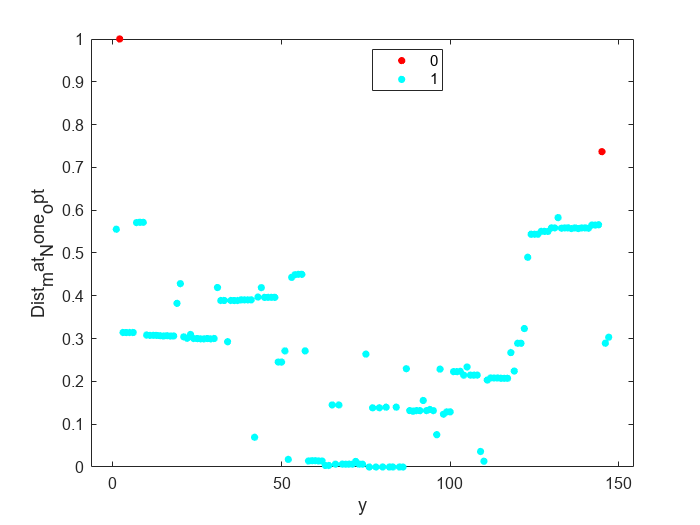

optrank_Insm = 2

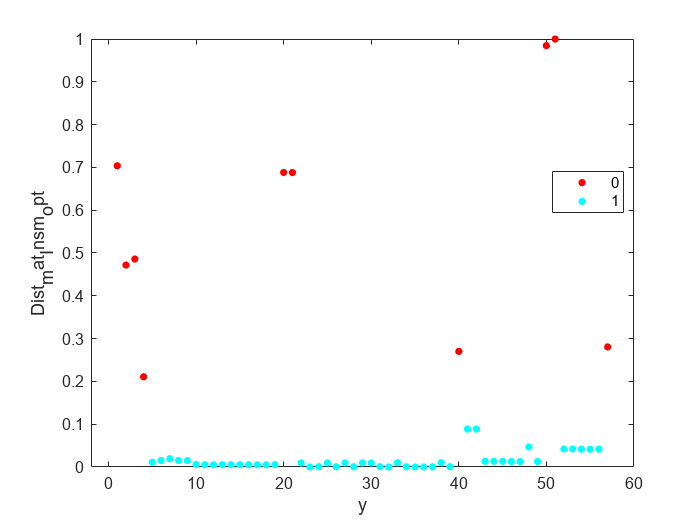

optrank_SA = 3

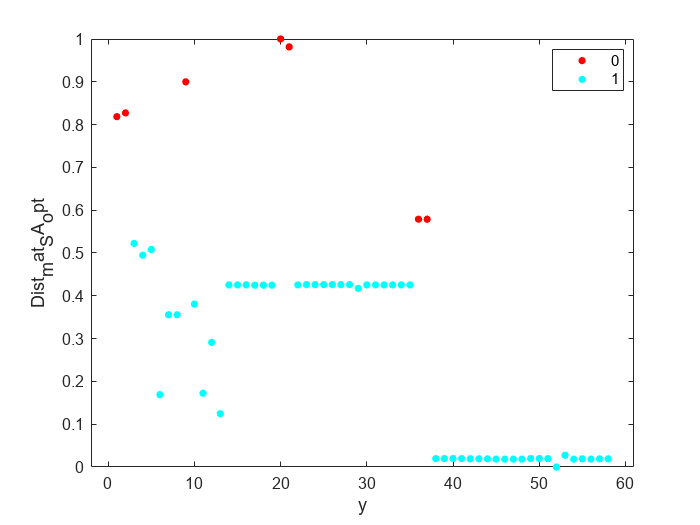

per = 10

optrank_None = 3

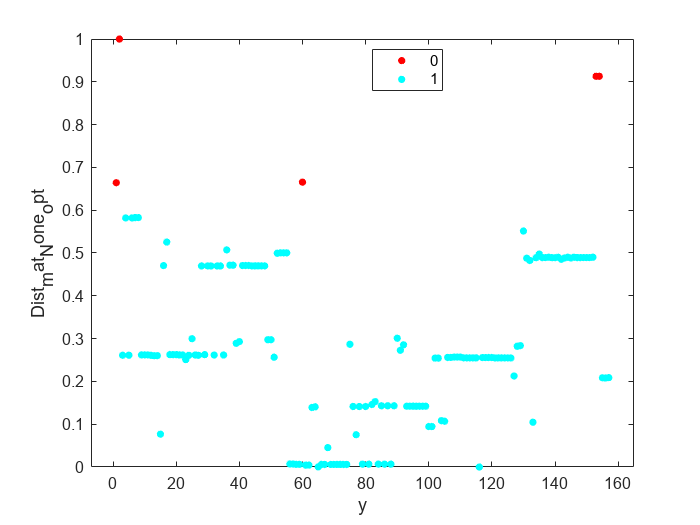

optrank_Insm = 3

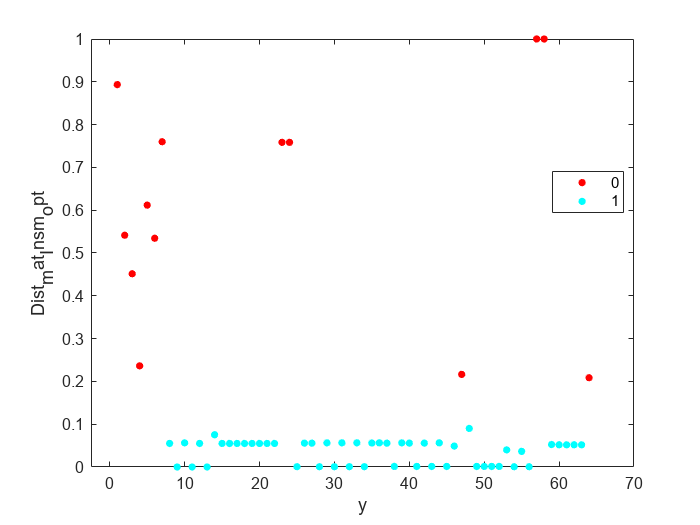

optrank_SA = 2

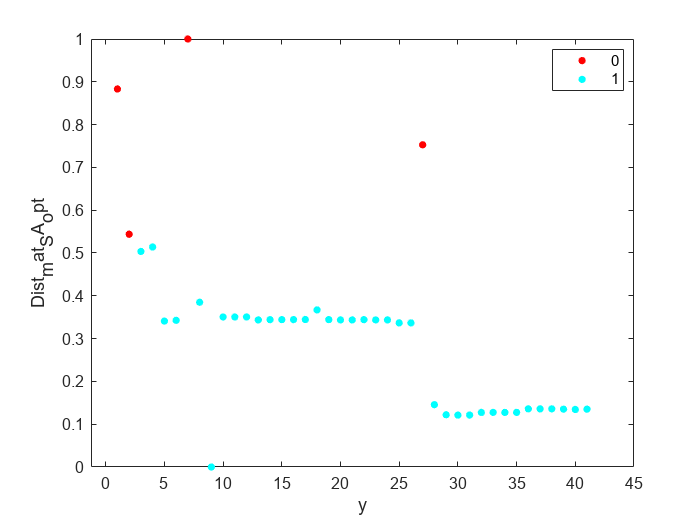

per = 10

optrank_None = 1

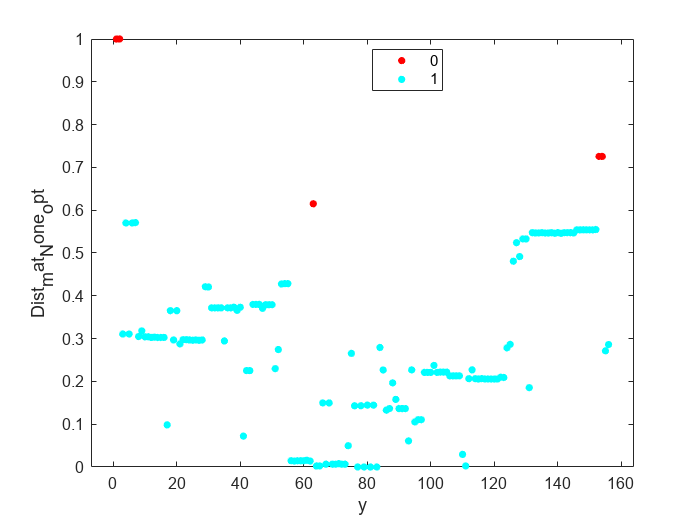

optrank_Insm = 3

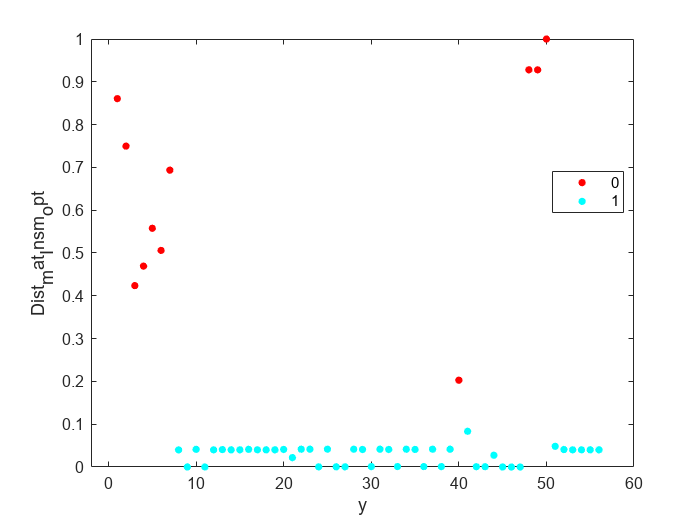

optrank_SA = 2

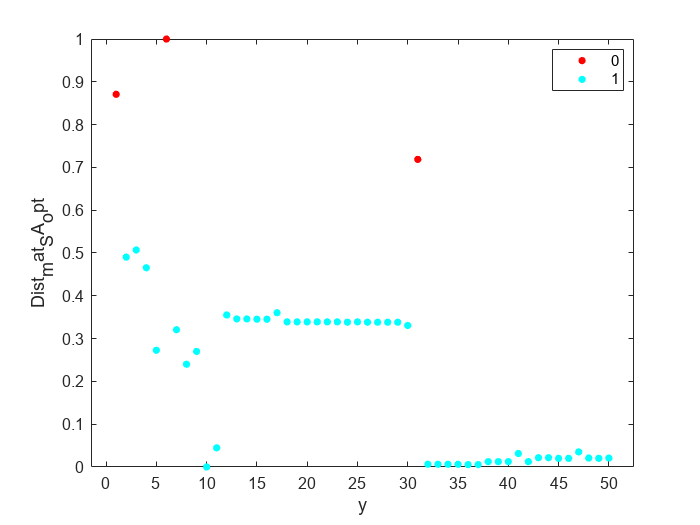

per = 10

optrank_None = 1

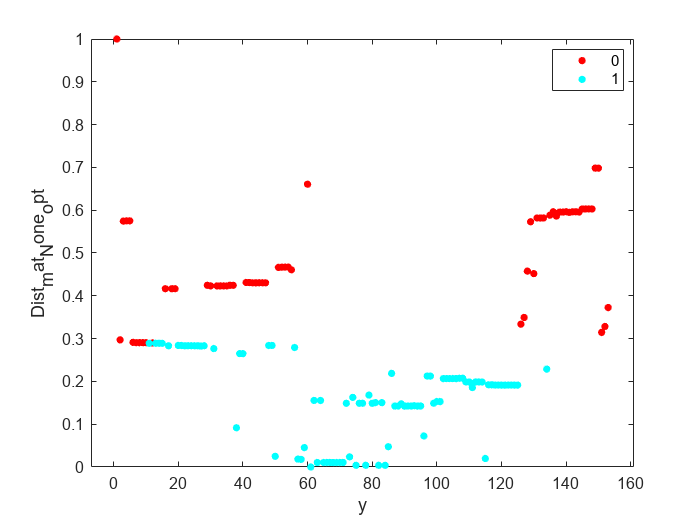

optrank_Insm = 2

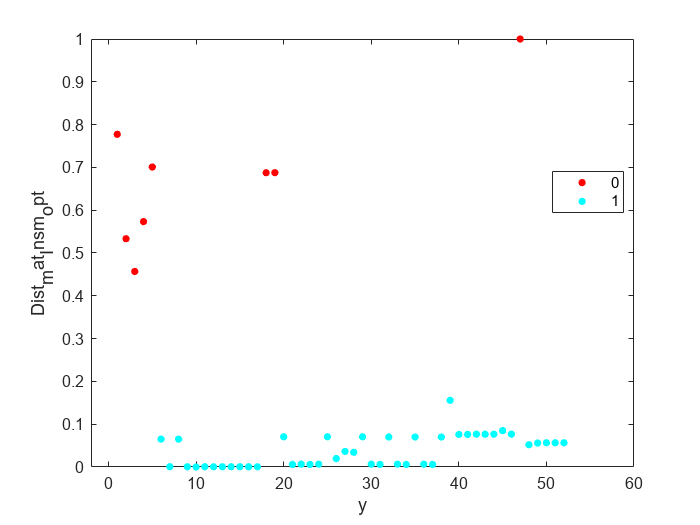

optrank_SA = 2

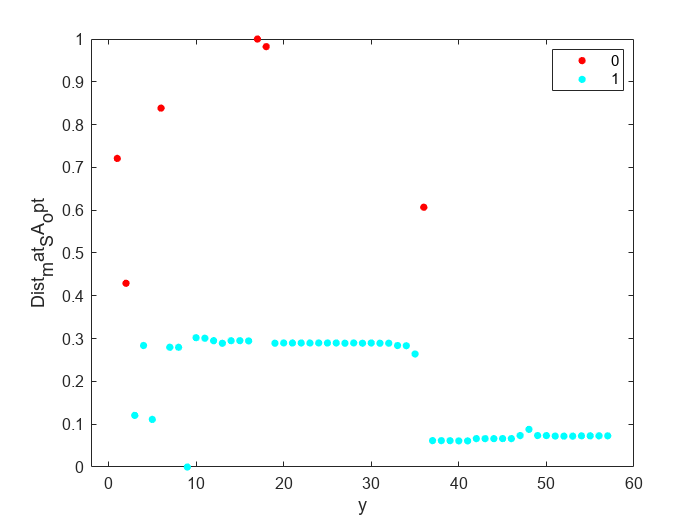

per = 10

optrank_None = 1

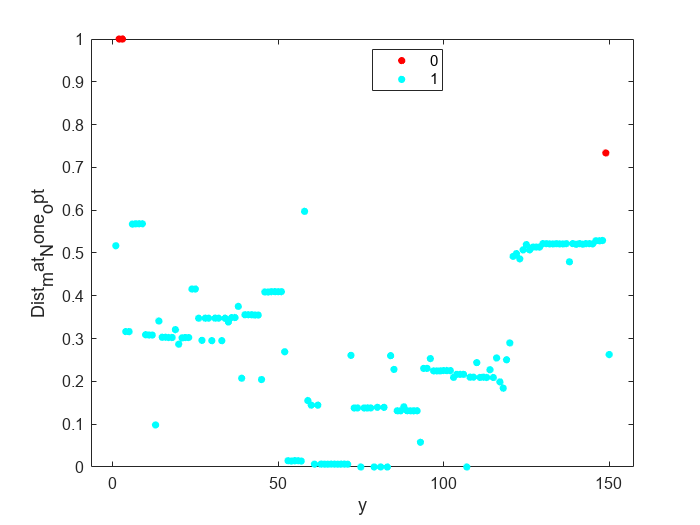

optrank_Insm = 1

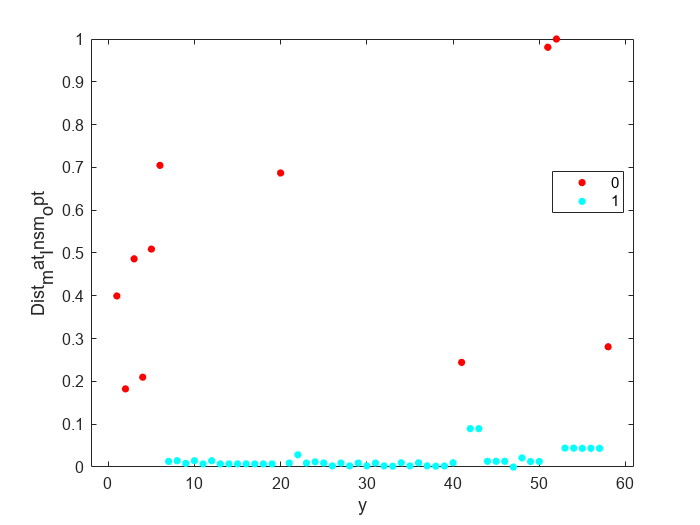

optrank_SA = 3

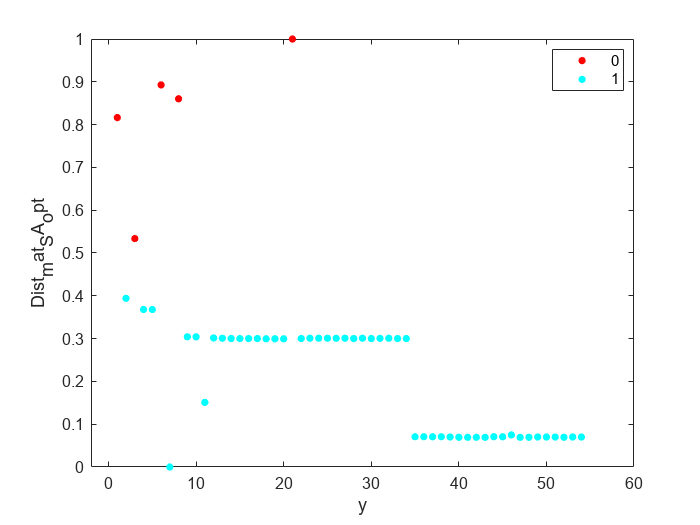

per = 10

optrank_None = 3

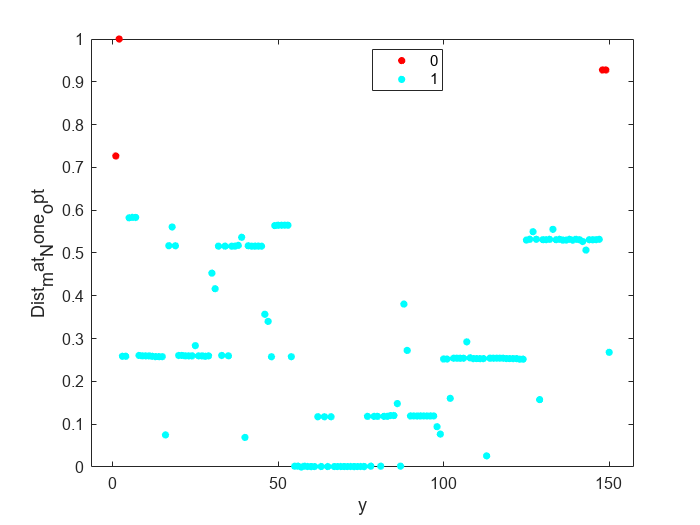

optrank_Insm = 3

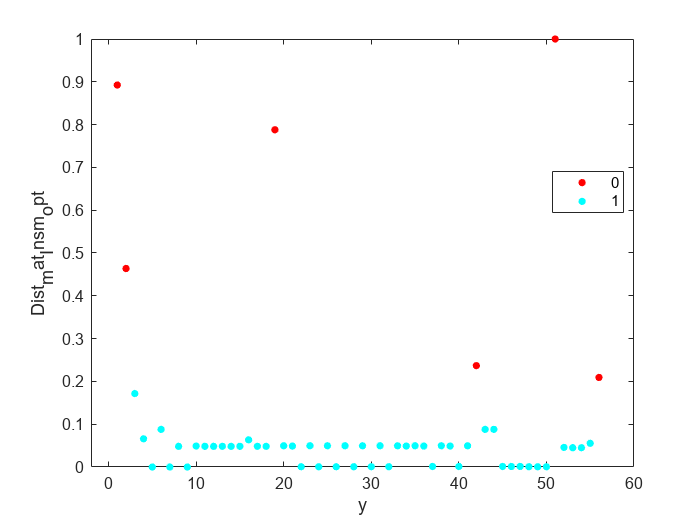

optrank_SA = 1

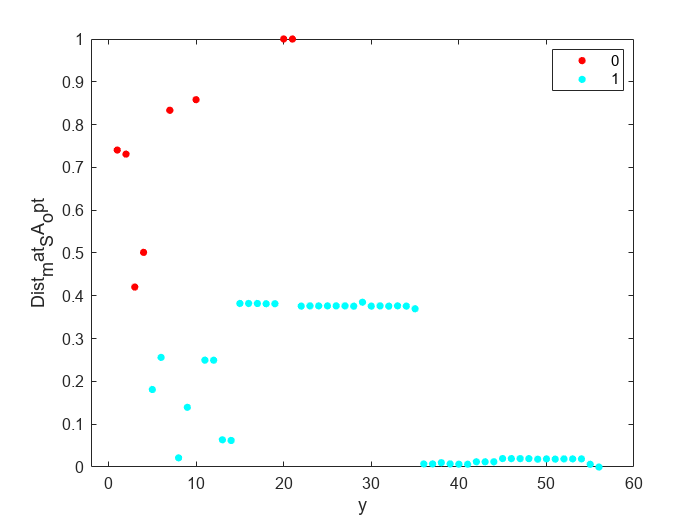

per = 10

optrank_None = 3

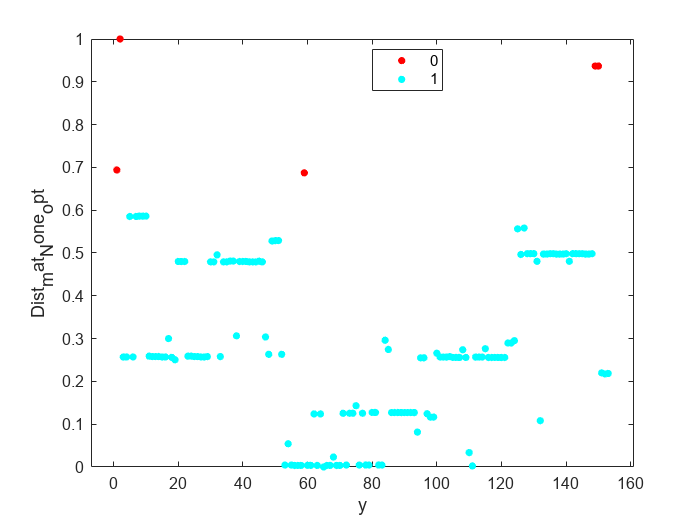

optrank_Insm = 3

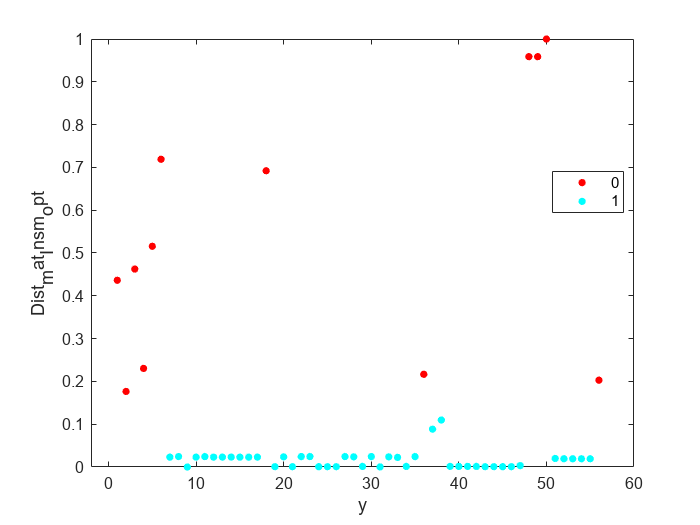

optrank_SA = 2

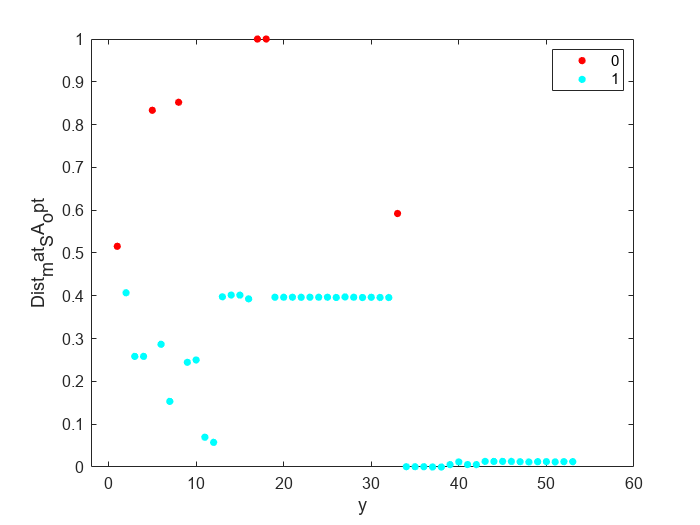

per = 10

optrank_None = 2

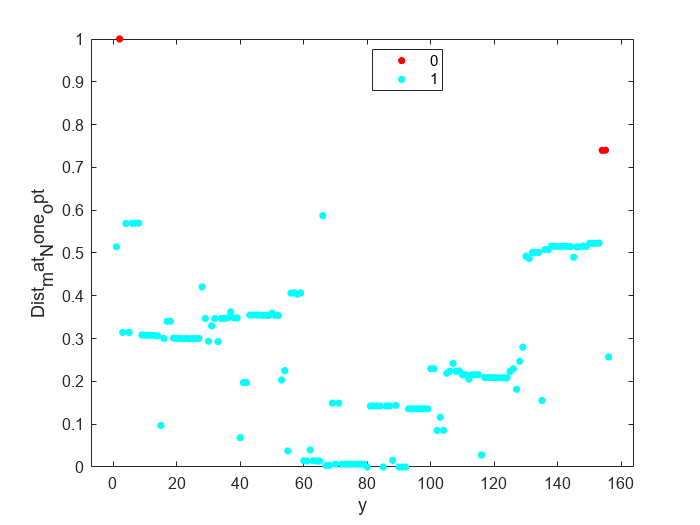

optrank_Insm = 3

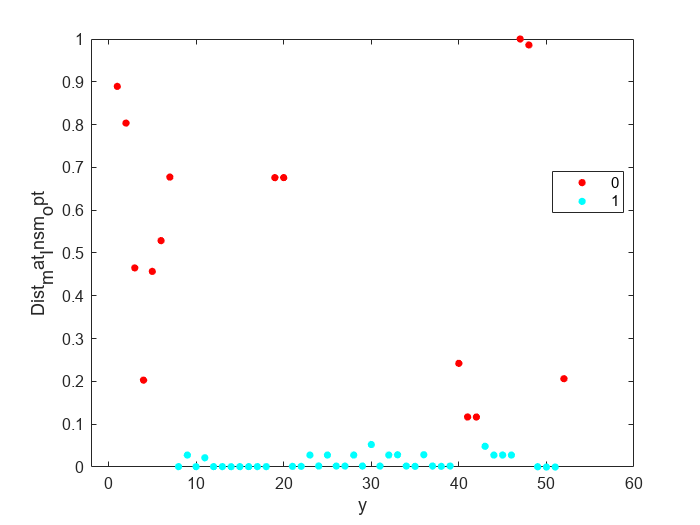

optrank_SA = 3

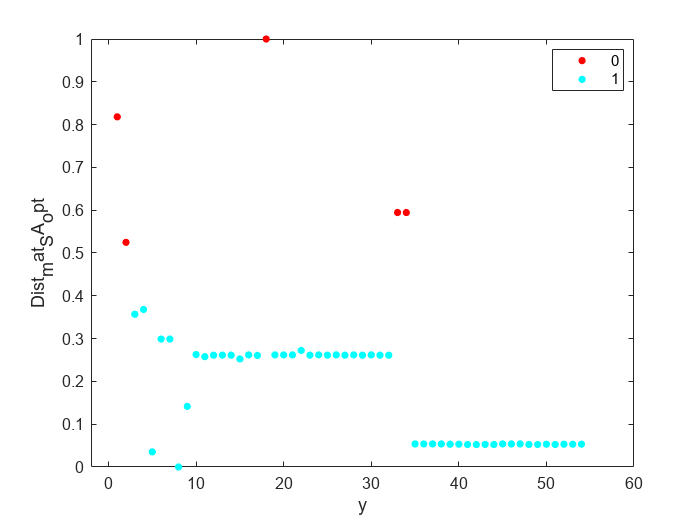

per = 10

optrank_None = 2

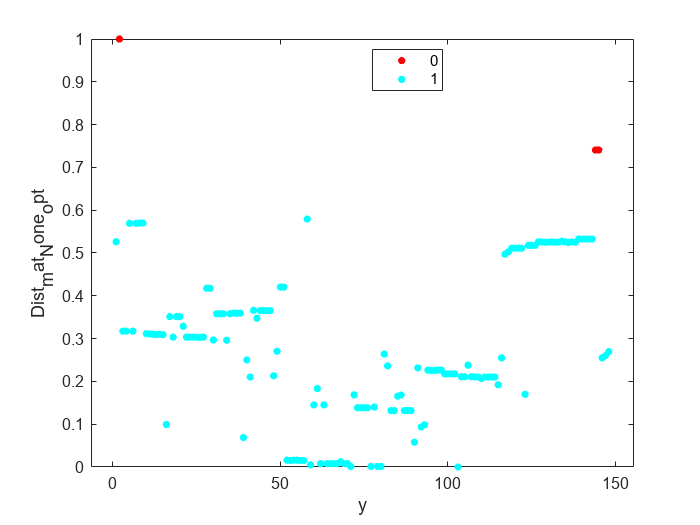

optrank_Insm = 3

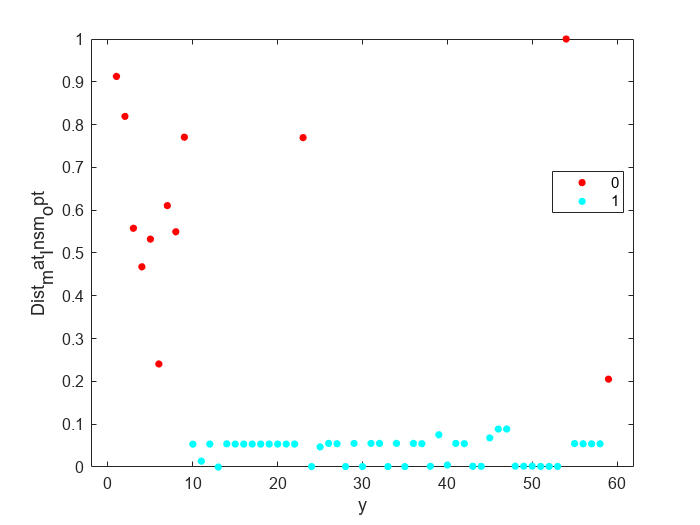

optrank_SA = 3

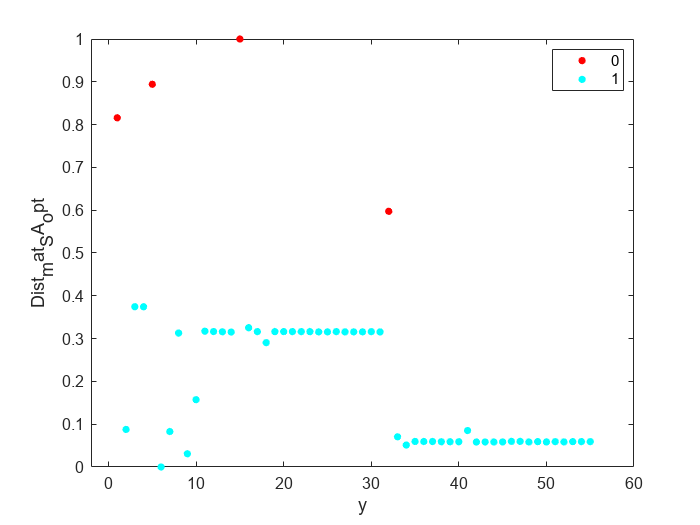

per = 10

optrank_None = 2

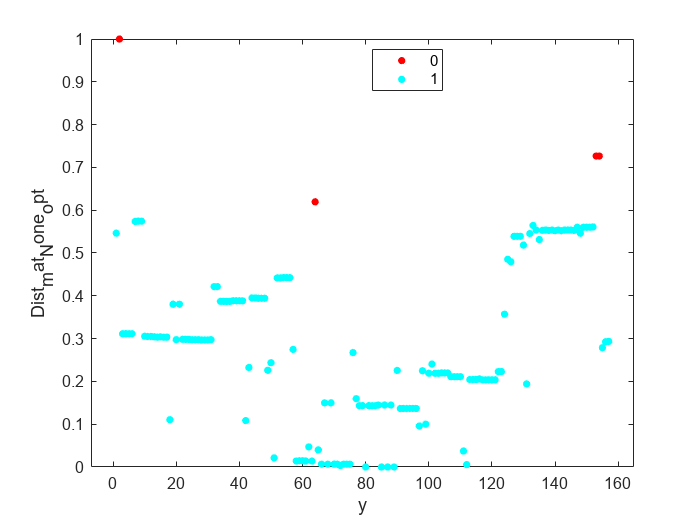

optrank_Insm = 3

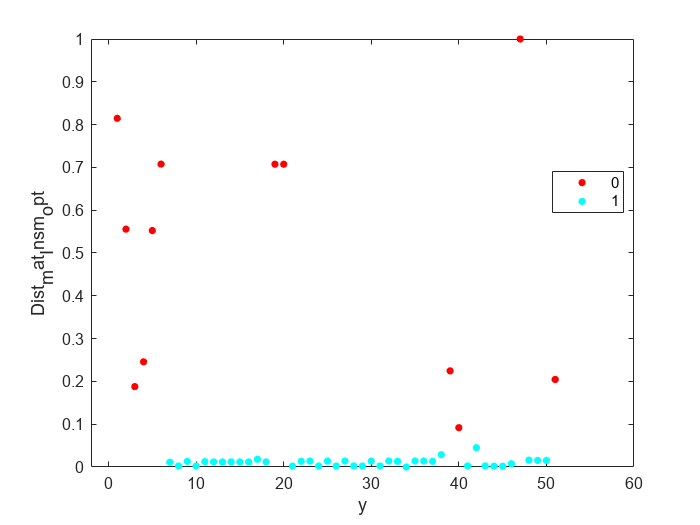

optrank_SA = 3

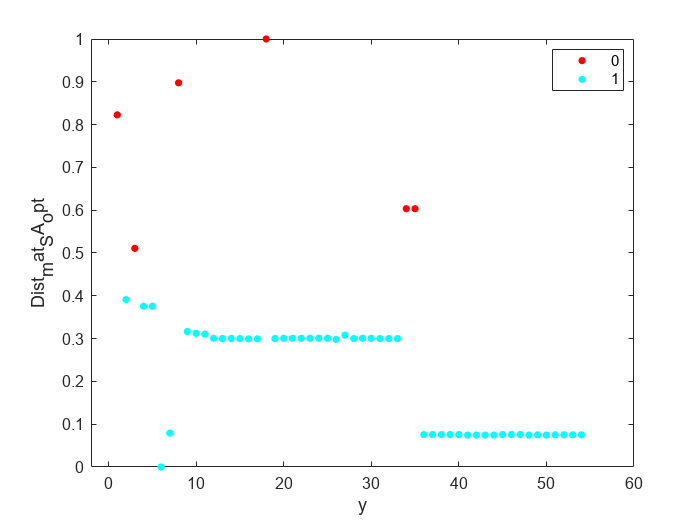

Error using importdata
Unable to open file.

for j = [1,2,3,4,5,6,7,8,9,10]

    splitfolder=strcat('split',num2str(j));
    M=importdata("C:\Users\shukl\Documents\GitHub\sleep\split1\sleep_train_set.csv",",",1);
    per =10%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\sleep\
        cd (splitfolder)

        fol= strcat('per',num2str(percent));
        cd (fol)

        my_file = strcat('sleep_noisy_per_',num2str(percent),'.csv');
        
        File=readmatrix(my_file,"NumHeaderLines",1);
        %per_folder= strcat('per',num2str(per));

        None=File(File(:,11)==0,1:10);
        T_None=None.';
        T_None_org=None.';

        Insm=File(File(:,11)==1,1:10);
        T_Insm=Insm.';
        T_Insm_org=Insm.';

        SA=File(File(:,11)==2,1:10);
        T_SA=SA.';
        T_SA_org=SA.';

        folder=strcat('ACE_dist_optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder);
        cd (folder);

        ranks=[1,2,3];

        error_None = nan(size(ranks));
        numNone=length(T_None);
        Dist_mat_None_array_asc=nan(length(ranks),numNone);
        threshold_rank_None=nan(size(ranks));
        elbow_indx_rank_None=nan(size(ranks));


        for i = ranks
            %#fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Decision-Trees\

            T_None_temp=T_None;
            Dist_mat_None=[];


            BF_None=l1pca_BF(T_None,i,1,10,10,'');
            for k = 1 : numNone
                A=T_None(:,k);
                Dist_mat_None(k)=norm((A-(BF_None*BF_None.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_None,[],"all");
            max_val=max(Dist_mat_None,[],"all");
            Dist_mat_None= Dist_mat_None-min_val;%]/[max_val-min_val]
            Dist_mat_None=Dist_mat_None /(max_val-min_val);


            Dist_mat_None_array_asc(i,:)=Dist_mat_None;
            [Dist_mat_None_asc,Indx_None]=sort(Dist_mat_None,"ascend");


            [elbow_None_err_angle,elbow_indx_None]=knee_pt_angle(Dist_mat_None_asc);

            error_None(i)=elbow_None_err_angle;
            threshold_rank_None(i)=Dist_mat_None_asc(elbow_indx_None);
            elbow_indx_rank_None(i)=elbow_indx_None;


%             figure
%             plot(Dist_mat_None_asc,'-p',"MarkerIndices",(elbow_indx_None),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance None Asc for rank", num2str(i)])
%             title(['Rank =',num2str(i) ])
% %             cd (splitfolder)
% %             cd (folder)
%             print(gcf,strcat('None',num2str(j),num2str(i),'.png'),'-dpng');

        end

        [~,optrank_None]= max(error_None)

        Dist_mat_None_opt=Dist_mat_None_array_asc(optrank_None,:);
        threshold_dist_None= threshold_rank_None(optrank_None);
        elbow_indx_None_opt=elbow_indx_rank_None(optrank_None);

        ind_O_None=find(Dist_mat_None_opt>threshold_dist_None);
        ind_I_None=find(Dist_mat_None_opt<=threshold_dist_None);


        cluster_None=zeros(size(Dist_mat_None_opt));
        cluster_None(ind_I_None)=1;
        figure
        y= 1:1:length(None);
        numGroups = length(unique(cluster_None));
        gscatter(y,Dist_mat_None_opt,cluster_None,hsv(numGroups))

        figure
        plot(sort(Dist_mat_None_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_None_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel(["Distance None Asc for opt rank",num2str(optrank_None)])
        title(['Rank opt for None =',num2str(optrank_None),"Split=",num2str(j)])

        print(gcf,strcat('Rank_Opt_None',num2str(j),'.png'),'-dpng');

        
        
        ind_O_None;


        T_None_temp(:,ind_O_None)=[];
        length(T_None_temp);

        Final_None=T_None_temp';
        Final_None(:,11)=0;

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        error_Insm = nan(size(ranks));
        numInsm=length(T_Insm);
        Dist_mat_Insm_array_asc=nan(length(ranks),numInsm);
        threshold_rank_Insm=nan(size(ranks));
        elbow_indx_rank_Insm=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Decision-Trees\

            T_Insm_temp=T_Insm;
            Dist_mat_Insm=[];


            BF_Insm=l1pca_BF(T_Insm,i,1,10,10,'');
            for k = 1 : numInsm
                A=T_Insm(:,k);
                Dist_mat_Insm(k)=norm((A-(BF_Insm*BF_Insm.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_Insm,[],"all");
            max_val=max(Dist_mat_Insm,[],"all");
            Dist_mat_Insm= Dist_mat_Insm-min_val;%]/[max_val-min_val]
            Dist_mat_Insm=Dist_mat_Insm /(max_val-min_val);


            Dist_mat_Insm_array_asc(i,:)=Dist_mat_Insm;
            [Dist_mat_Insm_asc,Indx_Insm]=sort(Dist_mat_Insm,"ascend");


            [elbow_Insm_err,elbow_indx_Insm]=knee_pt_angle((Dist_mat_Insm_asc));

            error_Insm(i)=elbow_Insm_err;
            threshold_rank_Insm(i)=Dist_mat_Insm_asc(elbow_indx_Insm);
            elbow_indx_rank_Insm(i)=elbow_indx_Insm;

%             figure
%             plot(Dist_mat_Insm_asc,'-p',"MarkerIndices",(elbow_indx_Insm),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance Insm Asc for rank", num2str(i)])
%             title(['Rank =',num2str(i) ])
% %             cd (splitfolder)
% %             cd (folder)
%             print(gcf,strcat('Insm',num2str(j),num2str(i),'.png'),'-dpng');
%             


        end

        [~,optrank_Insm]= max(error_Insm)

        Dist_mat_Insm_opt=Dist_mat_Insm_array_asc(optrank_Insm,:);
        threshold_dist_Insm= threshold_rank_Insm(optrank_Insm);
        elbow_indx_Insm_opt=elbow_indx_rank_Insm(optrank_Insm);

        ind_O_Insm=find(Dist_mat_Insm_opt>threshold_dist_Insm);
        ind_I_Insm=find(Dist_mat_Insm_opt<=threshold_dist_Insm);


        cluster_Insm=zeros(size(Dist_mat_Insm_opt));
        cluster_Insm(ind_I_Insm)=1;
        figure
        y= 1:1:length(Insm);
        numGroups = length(unique(cluster_Insm));
        gscatter(y,Dist_mat_Insm_opt,cluster_Insm,hsv(numGroups))

        figure
        plot(sort(Dist_mat_Insm_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_Insm_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel(["Distance Insm Asc for opt rank",num2str(optrank_Insm)])
        title(['Rank opt for Insm =',num2str(optrank_Insm),"Split=",num2str(j)])

        print(gcf,strcat('Rank_Opt_Insm',num2str(j),'.png'),'-dpng');

        ind_O_Insm;


        T_Insm_temp(:,ind_O_Insm)=[];
        length(T_Insm_temp);

        Final_Insm=T_Insm_temp';
        Final_Insm(:,11)=1;

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        error_SA = nan(size(ranks));
        numSA=length(T_SA);
        Dist_mat_SA_array_asc=nan(length(ranks),numSA);
        threshold_rank_SA=nan(size(ranks));
        elbow_indx_rank_SA=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\Decision-Trees\

            T_SA_temp=T_SA;
            Dist_mat_SA=[];


            BF_SA=l1pca_BF(T_SA,i,1,10,10,'');
            for k = 1 : numSA
                A=T_SA(:,k);
                Dist_mat_SA(k)=norm((A-(BF_SA*BF_SA.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_SA,[],"all");
            max_val=max(Dist_mat_SA,[],"all");
            Dist_mat_SA= Dist_mat_SA-min_val;%]/[max_val-min_val]
            Dist_mat_SA=Dist_mat_SA /(max_val-min_val);


            Dist_mat_SA_array_asc(i,:)=Dist_mat_SA;
            [Dist_mat_SA_asc,Indx_SA]=sort(Dist_mat_SA,"ascend");


            [elbow_SA_err,elbow_indx_SA]=knee_pt_angle((Dist_mat_SA_asc));

            error_SA(i)=elbow_SA_err;
            threshold_rank_SA(i)=Dist_mat_SA_asc(elbow_indx_SA);
            elbow_indx_rank_SA(i)=elbow_indx_SA;

%             figure
%             plot(Dist_mat_SA_asc,'-p',"MarkerIndices",(elbow_indx_SA),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance SA Asc for rank", num2str(i)])
%             title(['Rank =',num2str(i) ])
% %             cd (splitfolder)
% %             cd (folder)
%             print(gcf,strcat('SA',num2str(j),'.png'),'-dpng');


        end

        [~,optrank_SA]= max(error_SA)

        Dist_mat_SA_opt=Dist_mat_SA_array_asc(optrank_SA,:);
        threshold_dist_SA= threshold_rank_SA(optrank_SA);
        elbow_indx_SA_opt=elbow_indx_rank_SA(optrank_SA);

        ind_O_SA=find(Dist_mat_SA_opt>threshold_dist_SA);
        ind_I_SA=find(Dist_mat_SA_opt<=threshold_dist_SA);


        cluster_SA=zeros(size(Dist_mat_SA_opt));
        cluster_SA(ind_I_SA)=1;
        figure
        y= 1:1:length(SA);
        numGroups = length(unique(cluster_SA));
        gscatter(y,Dist_mat_SA_opt,cluster_SA,hsv(numGroups))

        figure
        plot(sort(Dist_mat_SA_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_SA_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel(["Distance SA Asc for opt rank",num2str(optrank_SA)])
        title(['Rank opt for SA =',num2str(optrank_SA),"Split=",num2str(j)])

        print(gcf,strcat('Rank_Opt_SA',num2str(j),num2str(i),'.png'),'-dpng');


        ind_O_SA;


        T_SA_temp(:,ind_O_SA)=[];
        length(T_SA_temp);

        Final_SA=T_SA_temp';
        Final_SA(:,11)=2;

        cd C:\Users\shukl\Documents\GitHub\Decision-Trees
        %mkdir (splitfolder)
        cd (splitfolder)
        %cd (per_folder)
        mkdir (folder)
        cd (folder)

        L1pca_file=(horzcat(Final_None.',Final_Insm.',Final_SA.')).';
        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:11)=M.colheaders;
        filel1pca_3=strcat('sleep_noisy_per',num2str(percent),'_ACE_l1pca.csv');
        writetable(L1pca_file,filel1pca_3)

        cd ..\
    end
    cd ..\..\
end